# Transformacja odwrotna – perfekcyjna rekonstrukcja

to get results run exc01

clear all

S = A.';

if eye(N) == S*A
    disp("SA==I")
else
    disp("SA!=I")
end

SA!=I



% random values matrix 20x20 
rand_matrix = zeros(N,N,100);
X_matrix = zeros(N,N,100);
xs_matrix = zeros(N,N,100);
similarity_matrix = zeros(1,100);
for i=1:100
    rand_matrix(:,:,i) = randn(N);
    X_matrix(:,:,i) = A*rand_matrix(:,:,i);
    xs_matrix(:,:,i) = S*X_matrix(:,:,i);
    similarity_matrix(i) = norm(rand_matrix(:,:,i)-xs_matrix(:,:,i));
end

similarity_matrix

similarity_matrix =     4.4517    3.8915    3.8333    3.8888    3.3894    4.5753    3.7048    5.2451    4.4448    2.8964    3.0341    3.2510    3.7216    4.8751    3.5029    3.9864    3.6881    5.0427    3.3045    5.4336    4.2824    4.4637    4.3689    3.9862    3.8564    3.8752    4.1618    4.5226    5.5513    4.2382    4.5373    5.0600    4.7081    3.7048    4.4257    4.0504    4.6500    3.6510    4.4975    3.6944    3.0291    5.6735    4.0307    4.2530    3.6774    3.5879    4.2347    3.5668    4.0665    4.2545


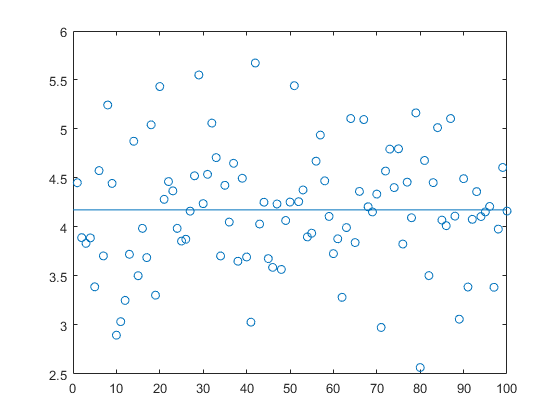


clf
figure
plot(similarity_matrix, 'o')
hold on 
hline = refline([0 mean(similarity_matrix)]);